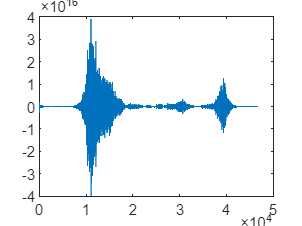

tspan = [0 90]; % Simulate over 60 minutes
EDA = load("EDA_preprocessed\S4M1EDA.mat");  % EDA
EDA = EDA.S4M1EDA;
figure
plot(EDA)

EDA = EDA.*10^-6;
EDA = EDA'

EDA = 1.0e+10 *

         0
   -0.2711
    0.1191
    0.1853
   -0.1731
   -0.0722
    0.1525
   -0.0088
   -0.0955
    0.0397


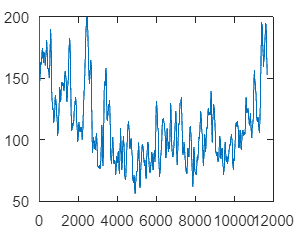


HR = load("Data\M1\HeartRate\S4HR.csv");% HR
figure
plot(HR)
ylim([50 200])

fs_EDA = 4;
fs_HR = 1;
t_EDA = ((0:length(EDA)-1) / fs_EDA);
t_HR = ((0:length(HR)-1) / fs_HR);




%% Interpolating data
C0 = 0;  % Initial cognitive load
EDA = @(t) interp1(t_EDA, EDA, t, 'linear')

EDA = function_handle with value:
    @(t)interp1(t_EDA,EDA,t,'linear')


HR = @(t) interp1(t_HR, HR, t, 'linear');


t_start = max(min(t_EDA), min(t_HR));
t_end = min(max(t_EDA), max(t_HR));

  % Adjust 0.1 as needed for resolution
alpha = 1.2;
beta = 0.8;
gamma = 0.5;

dCdt = @(t, C) alpha * EDA(t) + beta * HR(t) - gamma * C;
C0 = 0;

[t_sol, C_sol] = ode45(dCdt, [t_start, t_end], C0);

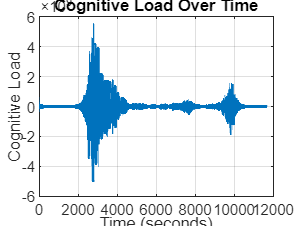


figure;
plot(t_sol, C_sol, 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Cognitive Load');
title('Cognitive Load Over Time');
grid on;


CL_range = max(C_sol) - min(C_sol)

CL_range = 1.0444e+10